# LME Tutorial 3: Control group

## Global parameters

clear % clear workspace
close all % close figures
% seed = 'shuffle'; % random seed
seed = 0;
rng(seed); % set random seed
N = 100; % number of subjects

## With control group

Measurement error

eps = 0.01;

Initial weight distribution

Weight1_true = 70 + 5*randn(N,1);
Weight1 = Weight1_true + eps*randn(N,1);

Linear term

vpa(expand(0.1 + 1/mean(Weight1_true)*(sym('Initial')-50)),4)

$$ans = 0.01416\,\mathrm{Initial}-0.6081$$

Final weight

Weight2 = Weight1_true + 0.1 + (1/mean(Weight1_true))*(Weight1_true-50) + eps*randn(N,1);

Control group

Nc = 50;
Weight1c_true = 70 + 5*randn(Nc,1);
Weight1c = Weight1c_true + eps*randn(Nc,1);
Weight2c = Weight1c_true + eps*randn(Nc,1);

Create Dataset

Subject1 = (1:N)';
Initial1 = Weight1;
Gain1 = Weight2-Weight1;
Group1 = repmat({'treat'},N,1);
Subject2 = (N+1:N+Nc)';
Initial2 = Weight1c;
Gain2 = Weight2c-Weight1c;
Group2 = repmat({'ctrl'},Nc,1);
Subject = [Subject1;Subject2];
Initial = [Initial1;Initial2];
Gain = [Gain1;Gain2];
Group = [Group1;Group2];

Data = table;
Data.Subject = Subject;
Data.Initial = Initial;
Data.Gain = Gain;
Data.Group = Group;
% convert to categorical
Data.Subject = categorical(Data.Subject);
Data.Group = categorical(Data.Group);
% sort by subject
Data = sortrows(Data,{'Subject'});
head(Data)

ans = 8×4 table
    Subject        Initial               Gain           Group
    _______    ________________    _________________    _____

       1        72.696739453028    0.414722840145714    treat
       2       79.1605447521521    0.511657046283887    treat
       3       58.7067666233132    0.231775480182542    treat
       4       74.3054213125407     0.45278723477567    treat
       5       71.5968614072414    0.404111283675149    treat
       6       63.4555552528523    0.301787707709018    treat
       7       67.8369395416833    0.350237700263733    treat
       8       71.7205159639293    0.390675631043933    treat


% save data table to Excel file
writetable(Data,'Chocolate_LM3.xlsx', 'WriteMode', 'replacefile');

Histogram with Gaussian fit

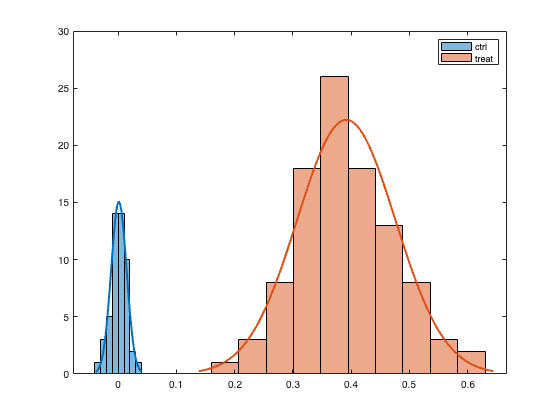

figure
cmap = colormap('lines');
h1 = histfit(Gain2);
h1(1).FaceColor = cmap(1,:);
h1(1).FaceAlpha = 0.5;
h1(2).Color = cmap(1,:);
hold on
h2 = histfit(Gain1);
h2(1).FaceColor = cmap(2,:);
h2(1).FaceAlpha = 0.5;
h2(2).Color = cmap(2,:);
legend([h1(1), h2(1)],{'ctrl','treat'})
hold off

Gain versus initial weight

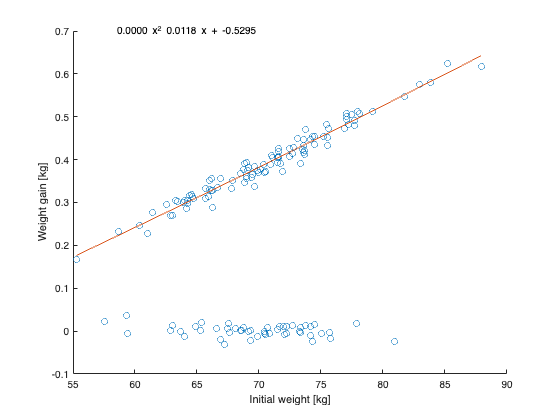

scatter(Initial,Gain)
hold on
a = polyfit(Initial1,Gain1,2);
x1 = linspace(min(Initial1),max(Initial1));
y1 = polyval(a,x1);
plot(x1,y1);
text(0.1,1,sprintf('%.4f x^2 %.4f x + %.4f',a(1),a(2),a(3)),'Units','normalized');
hold off
xlabel('Initial weight [kg]');
ylabel('Weight gain [kg]');

## T-test

[~,p] = ttest2(Gain1,Gain2) % unpaired

p =      3.173245000710038e-69


## Group as random effect

formula = 'Gain ~ Initial + (1|Group)';
mdl1 = fitlme(Data,formula,'DummyVarCoding','effects');
stats1 = anova(mdl1) 

stats1 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat               DF1    DF2    pValue              
    {'(Intercept)'}        14.8589963052117    1      148    0.000172227164192667
    {'Initial'    }         330.49989419186    1      148    1.52494454760709e-39


## Group as random interaction effect

formula = 'Gain ~ Initial + (Initial|Group)';
mdl2 = fitlme(Data,formula,'DummyVarCoding','effects');
stats2 = anova(mdl2) 

stats2 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat               DF1    DF2    pValue           
    {'(Intercept)'}          1.375841867035    1      148    0.242695088796895
    {'Initial'    }        1.59594309187603    1      148    0.208465560211643


## Group as fixed effect

formula = 'Gain ~ Group + Initial';
mdl3 = fitlme(Data,formula,'DummyVarCoding','effects');
stats3 = anova(mdl3) 

stats3 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat               DF1    DF2    pValue               
    {'(Intercept)'}        179.056970269584    1      147      3.2815976117211e-27
    {'Initial'    }        334.855588440086    1      147     9.97089202676756e-40
    {'Group'      }        3254.30453921739    1      147    3.53902300864118e-102


## Group as fixed interaction effect

formula = 'Gain ~ Group * Initial';
mdl4 = fitlme(Data,formula,'DummyVarCoding','effects');
stats4 = anova(mdl4) 

stats4 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                     FStat               DF1    DF2    pValue              
    {'(Intercept)'  }        246.298045362383    1      146    3.82080501015763e-33
    {'Initial'      }        702.332299140006    1      146    1.17995119277377e-57
    {'Group'        }        356.642888181304    1      146     4.9905873310453e-41
    {'Initial:Group'}        878.904823933844    1      146    1.17426189403014e-63


Compare models

RSquared1 = mdl1.Rsquared.Ordinary

RSquared1 =    0.961902796382301


RSquared2 = mdl2.Rsquared.Ordinary

RSquared2 =    0.994450875711530


RSquared3 = mdl3.Rsquared.Ordinary

RSquared3 =    0.961942280829539


RSquared4 = mdl4.Rsquared.Ordinary

RSquared4 =    0.994451714344439


c12 = compare(mdl1,mdl2)

c12 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC                  BIC                  LogLik              LRStat              deltaDF    pValue
    mdl1     4     -527.806772065424    -515.764230889039    267.903386032712                                         
    mdl2     6     -808.676767945024    -790.612956180447    410.338383972512    284.869995879601    2          0     


c13 = compare(mdl1,mdl3)

c13 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC                  BIC                  LogLik              LRStat              deltaDF    pValue
    mdl1     4     -527.806772065424    -515.764230889039    267.903386032712                                         
    mdl3     4     -544.714500461333    -532.671959284948    276.357250230667    16.9077283959098    0          0     


c14 = compare(mdl1,mdl4)

c14 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC                  BIC                  LogLik              LRStat              deltaDF    pValue
    mdl1     4     -527.806772065424    -515.764230889039    267.903386032712                                         
    mdl4     5     -831.556742018199    -816.503565547718      420.7783710091    305.749969952776    1          0     


c23 = compare(mdl2,mdl3)

c23 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC                  BIC                  LogLik              LRStat               deltaDF    pValue
    mdl2     6     -808.676767945024    -790.612956180447    410.338383972512                                          
    mdl3     4     -544.714500461333    -532.671959284948    276.357250230667    -267.962267483691    -2         NaN   


c24 = compare(mdl2,mdl4)

c24 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC                  BIC                  LogLik              LRStat              deltaDF    pValue
    mdl2     6     -808.676767945024    -790.612956180447    410.338383972512                                         
    mdl4     5     -831.556742018199    -816.503565547718      420.7783710091    20.8799740731747    -1         NaN   


c34 = compare(mdl3,mdl4)

c34 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC                  BIC                  LogLik              LRStat              deltaDF    pValue
    mdl3     4     -544.714500461333    -532.671959284948    276.357250230667                                         
    mdl4     5     -831.556742018199    -816.503565547718      420.7783710091    288.842241556866    1          0     
